# CCLE Dataset Correlations

**Author:** Scott Campit

## Summary

This livescript computes correlations between CCLE datasets.

## Process datasets

### Entire dataset

% First we need to clean up the metabolomics dataset
metabolomics = readtable('CCLE_metabolomics_processed.xlsx', 'sheet', 'all')
metabolomics_ccl = extractBefore(string(table2cell(metabolomics(:, 'CCLE_ID'))), '_')
metabolomics(:, 'CCLE_ID') = cellstr(metabolomics_ccl)

% Next, we need to map between datasets
gcp = readtable('GCP_proteomics_remapped.xlsx', 'sheet', 'all')

[~, ia, ib] = intersect(string(table2cell(metabolomics(:, 'CCLE_ID'))), ...
                        string(table2cell(gcp(:, 'CellLine'))));
                    
% Finally, let's get tables with matching indicies
metabolomics = metabolomics(ia, :);
gcp = gcp(ib, :);

### Methylation and acetylation subsets

% I will also load data subsets and map them
methylation_metabolomics = readtable('CCLE_metabolomics_processed.xlsx', 'sheet', 'methylation')
methylation_metabolomics(:, 'CCLE_ID') = cellstr(metabolomics_ccl)
methylation_gcp = readtable('GCP_proteomics_remapped.xlsx', 'sheet', 'methylation')
methylation_metabolomics = methylation_metabolomics(ia, :);
methylation_gcp = methylation_gcp(ib, :);

acetylation_metabolomics = readtable('CCLE_metabolomics_processed.xlsx', 'sheet', 'acetylation')
acetylation_metabolomics(:, 'CCLE_ID') = cellstr(metabolomics_ccl)
acetylation_gcp = readtable('GCP_proteomics_remapped.xlsx', 'sheet', 'acetylation')
acetylation_metabolomics = acetylation_metabolomics(ia, :);
acetylation_gcp = acetylation_gcp(ib, :);

## Correlation between GCP and metabolomics

### Pearson correlation coefficient of the entire dataset

This module computes the Pearson and Spearman correlation matrix between each GCP and metabolite value pair. Then, it finds significant interactions. These can be plotted either in-line or through another programming language.

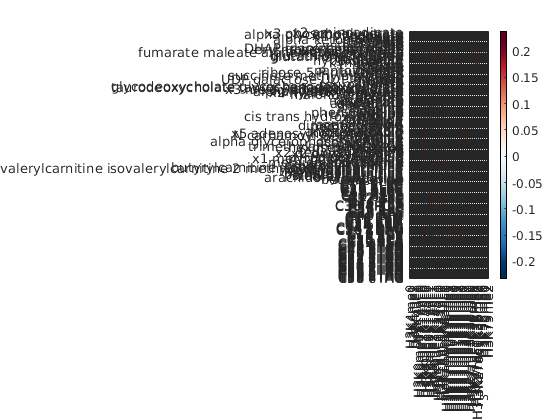

% Get data subsets
X = table2array(gcp(:, 2:end)); X(isnan(X)) = 0;
Y = table2array(metabolomics(:, 2:end)); Y(isnan(Y)) = 0;
metabolites = metabolomics.Properties.VariableNames(2:end);
markers = gcp.Properties.VariableNames(2:end);

% Compute pearson correlation coefficient matrix
[pearsonmat, pearsonpval] = corr(X, Y, ...
                                 'Type', 'Pearson');

% Plot correlation matrix without p-value mask                            
redbluecmap = imresize(redbluecmap, [1000, 3]); redbluecmap = min(max(redbluecmap, 0), 1);
metabolites = strrep(metabolites, '_', ' ');
heatmap(pearsonmat', 'colormap', redbluecmap, ...
        'YData', metabolites, ...
        'XData', markers)

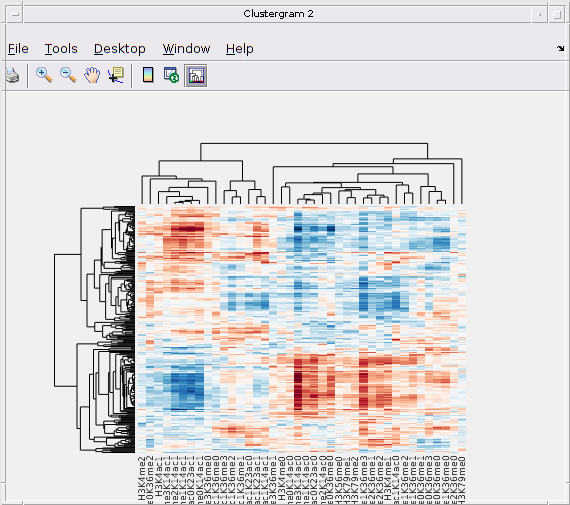

Clustergram object with 225 rows of nodes and 40 columns of nodes.



% Plot clustergram without p-value mask
clustergram(pearsonmat', ...
            'RowLabels', metabolites', ...
            'ColumnLabels', markers, ...
            'RowPdist', 'correlation', ...
            'ColumnPdist', 'correlation', ...
            'Colormap', redbluecmap)

#### Spearman rank correlation

I also wanted to look at rank correlations. Interestingly, the magnitude of the rank coefficients didnt change much. So I ommited this Spearman analysis for the remaining analyses.

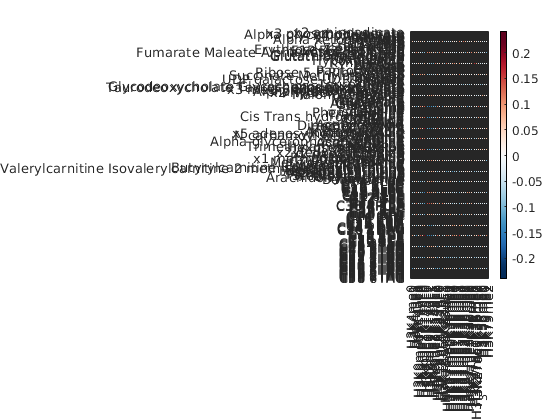

% Compute pearson correlation coefficient matrix
[spearmanmat, spearmanpval] = corr(X, Y, ...
                                 'Type', 'Spearman');

% Plot correlation matrix without p-value mask                            
redbluecmap = imresize(redbluecmap, [1000, 3]); redbluecmap = min(max(redbluecmap, 0), 1);
metabolites = strrep(metabolites, '_', ' ');
heatmap(spearmanmat', 'colormap', redbluecmap, ...
        'YData', metabolites, ...
        'XData', markers)

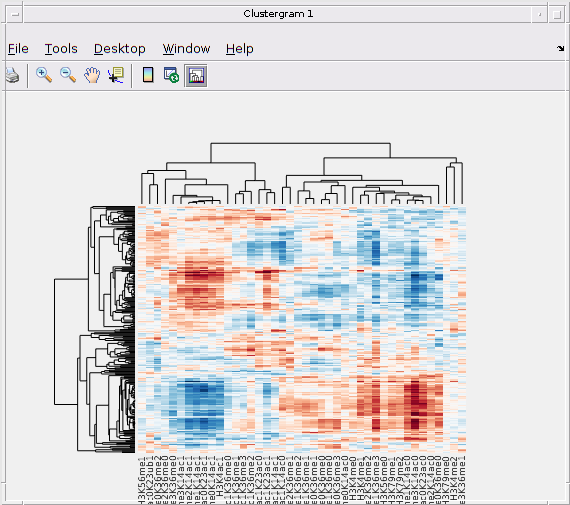

Clustergram object with 225 rows of nodes and 42 columns of nodes.



% Plot clustergram without p-value mask
clustergram(spearmanmat', ...
            'RowLabels', metabolites', ...
            'ColumnLabels', markers, ...
            'RowPdist', 'correlation', ...
            'ColumnPdist', 'correlation', ...
            'Colormap', redbluecmap)

### Applying a mask

Next, I decided to look at these matrices using the p-value mask. Because there are NaNs, we can't make a clustergram for this set. 

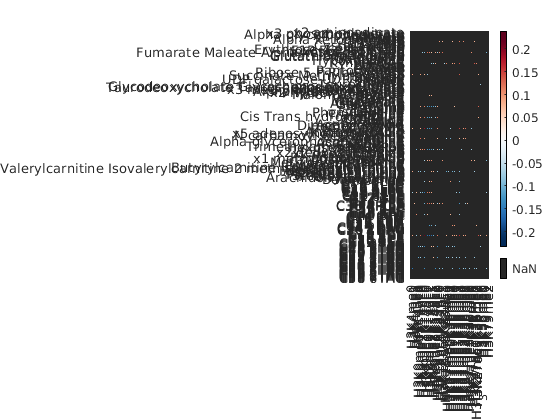

mask = pearsonmat;
mask(pearsonpval > 0.05) = NaN;

% Plot correlation matrix without p-value mask                            
heatmap(mask', 'colormap', redbluecmap, ...
        'YData', metabolites, ...
        'XData', markers)

### Metabolic subsets

#### All data

Of course, because we're showing all the histone markers and all metabolites, this is pretty terrible to analyze. Let's start simplifying by removing histone markers I'm not interested in analyzing.

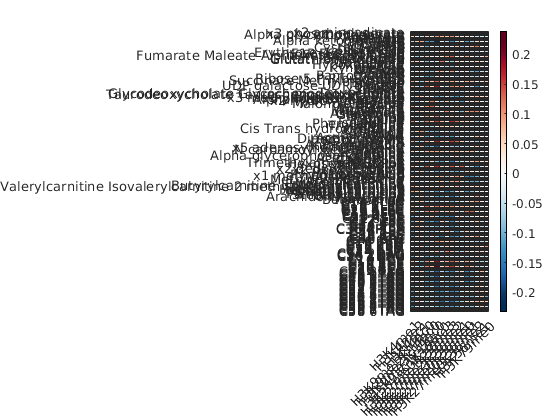

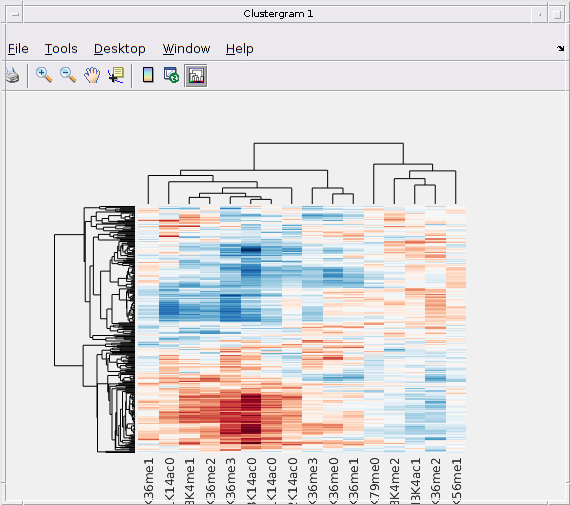

Clustergram object with 225 rows of nodes and 16 columns of nodes.



metabolic_subset = [2, 3, 4, ...        % H3K4
                    6, 7, 8, 9, ...     % H3K9
                    23, 27, 30, 32, ... % H3K27
                    20, 21, 22, ...     % H3K36
                    39, 40];            % H3K79
pearsonmat_metab = pearsonmat(metabolic_subset, :);
pearsonpval_metab = pearsonpval(metabolic_subset, :);
metab_markers = markers(metabolic_subset);
heatmap(pearsonmat_metab', 'colormap', redbluecmap, ...
        'YData', metabolites, ...
        'XData', metab_markers)
clustergram(pearsonmat_metab', ...
            'RowLabels', metabolites, ...
            'ColumnLabels', metab_markers, ...
            'RowPdist', 'correlation', ...
            'ColumnPdist', 'correlation', ...
            'Colormap', redbluecmap)

#### Mask

Add a p-value mask to this metabolic subset.

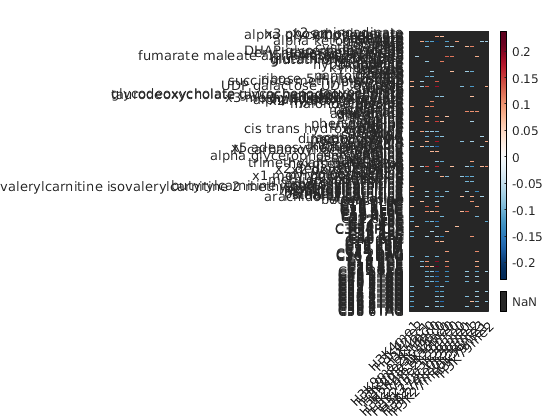

ans = 0.0615

ans = 0.0096

ans = 0.0144

ans = -0.0618

ans = 0.0343

ans = -0.0620

ans = 0.0155

ans = -0.0207

ans = -0.2740

ans = -0.1708

ans = 0.0267

ans = -0.0032

ans = 0.0398

ans = -0.0093

ans = -0.0290

ans = 0.0431

ans = -0.0557

ans = NaN

ans = -0.0548

ans = 0.2865

ans = NaN

ans = NaN

ans = -0.2741

ans = 0.1578

ans = NaN

ans = NaN

ans = -0.0738

ans = 0.0344

ans = NaN

ans = NaN

ans = -0.0104

ans = NaN

mask = pearsonmat_metab;
mask(pearsonpval_metab > 0.05) = NaN;

% Plot correlation matrix without p-value mask                            
heatmap(mask', 'colormap', redbluecmap, ...
        'YData', metabolites, ...
        'XData', metab_markers)

### Pearson correlation coefficient of the Methylation subset

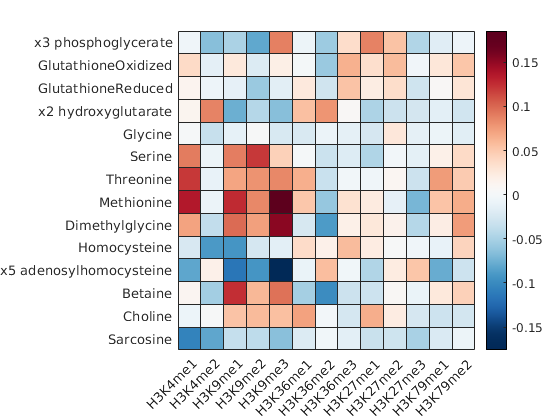

% Get data subsets
X = table2array(methylation_gcp(:, 2:end)); X(isnan(X)) = 0;
Y = table2array(methylation_metabolomics(:, 2:end)); Y(isnan(Y)) = 0;
metabolites = methylation_metabolomics.Properties.VariableNames(2:end);
markers = methylation_gcp.Properties.VariableNames(2:end);

% Compute pearson correlation coefficient matrix
[pearsonmat, pearsonpval] = corr(X, Y, ...
                                 'Type', 'Pearson');

% Plot correlation matrix without p-value mask                            
redbluecmap = imresize(redbluecmap, [1000, 3]); redbluecmap = min(max(redbluecmap, 0), 1);
metabolites = strrep(metabolites, '_', ' ');
heatmap(pearsonmat', 'colormap', redbluecmap, ...
        'YData', metabolites, ...
        'XData', markers)

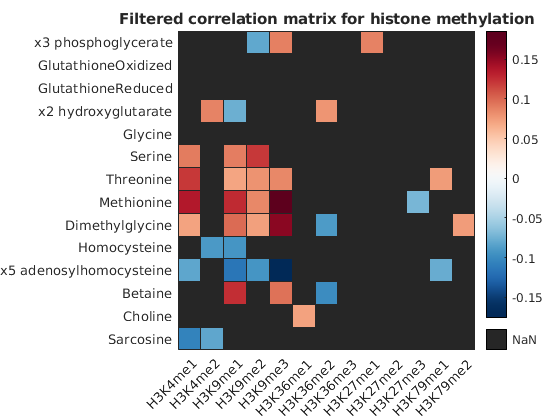

    
mask = pearsonmat;
mask(pearsonpval > 0.05) = NaN;

% Plot correlation matrix without p-value mask                            
heatmap(mask', 'colormap', redbluecmap, ...
        'YData', metabolites, ...
        'XData', markers, ...
        'Title', 'Filtered correlation matrix for histone methylation')

% Plot clustergram without p-value mask
clustergram(pearsonmat', ...
            'RowLabels', metabolites', ...
            'ColumnLabels', markers, ...
            'RowPdist', 'correlation', ...
            'ColumnPdist', 'correlation', ...
            'Colormap', redbluecmap)

Clustergram object with 14 rows of nodes and 13 columns of nodes.



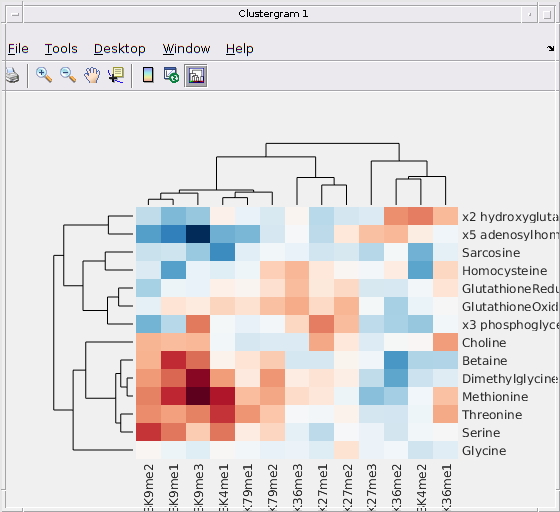

figureHandle = gcf;
%# make all text in the figure to size 14 and bold
set(findall(figureHandle,'type','text'), ...
            'fontSize',30,...
            'fontWeight','bold')

#### Spearman rank correlation

I also wanted to look at rank correlations. Interestingly, the magnitude of the rank coefficients didnt change much. So I ommited this Spearman analysis for the remaining analyses.

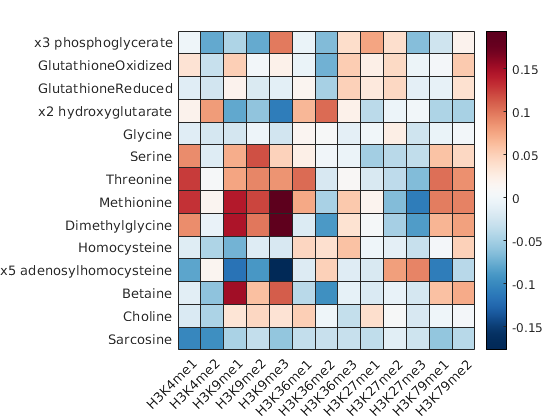

% Compute pearson correlation coefficient matrix
[spearmanmat, spearmanpval] = corr(X, Y, ...
                                 'Type', 'Spearman');

% Plot correlation matrix without p-value mask                            
redbluecmap = imresize(redbluecmap, [1000, 3]); redbluecmap = min(max(redbluecmap, 0), 1);
metabolites = strrep(metabolites, '_', ' ');
heatmap(spearmanmat', 'colormap', redbluecmap, ...
        'YData', metabolites, ...
        'XData', markers)

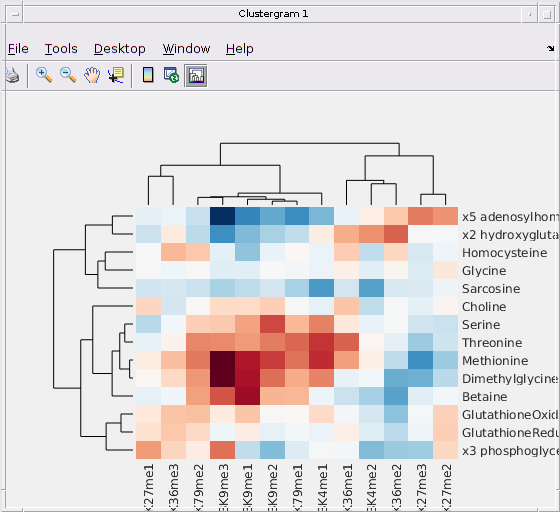

Clustergram object with 14 rows of nodes and 13 columns of nodes.



% Plot clustergram without p-value mask
clustergram(spearmanmat', ...
            'RowLabels', metabolites', ...
            'ColumnLabels', markers, ...
            'RowPdist', 'correlation', ...
            'ColumnPdist', 'correlation', ...
            'Colormap', redbluecmap)

### Applying a mask

Next, I decided to look at these matrices using the p-value mask. Because there are NaNs, we can't make a clustergram for this set. 

mask = pearsonmat;
mask(pearsonpval > 0.05) = NaN;

% Plot correlation matrix without p-value mask                            
heatmap(mask', 'colormap', redbluecmap, ...
        'YData', metabolites, ...
        'XData', markers)

### Pearson correlation coefficient of the Acetylation subset

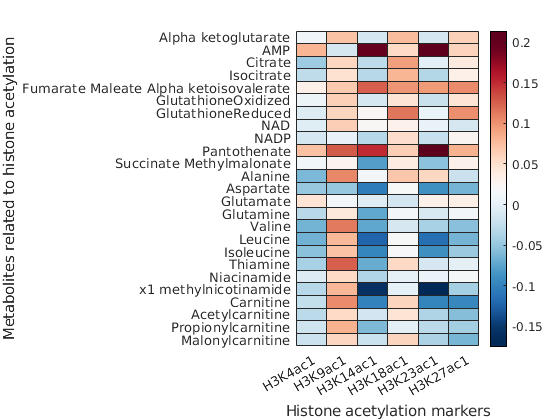

% Get data subsets
X = table2array(acetylation_gcp(:, 2:end)); X(isnan(X)) = 0;
Y = table2array(acetylation_metabolomics(:, 2:end)); Y(isnan(Y)) = 0;
metabolites = acetylation_metabolomics.Properties.VariableNames(2:end);
markers = acetylation_gcp.Properties.VariableNames(2:end);

% Compute pearson correlation coefficient matrix
[pearsonmat, pearsonpval] = corr(X, Y, ...
                                 'Type', 'Pearson');

% Plot correlation matrix without p-value mask                            
redbluecmap = imresize(redbluecmap, [1000, 3]); redbluecmap = min(max(redbluecmap, 0), 1);
metabolites = strrep(metabolites, '_', ' ');
heatmap(pearsonmat', 'colormap', redbluecmap, ...
        'YData', metabolites, ...
        'XData', markers)
xlabel('Histone acetylation markers');
ylabel('Metabolites related to histone acetylation')

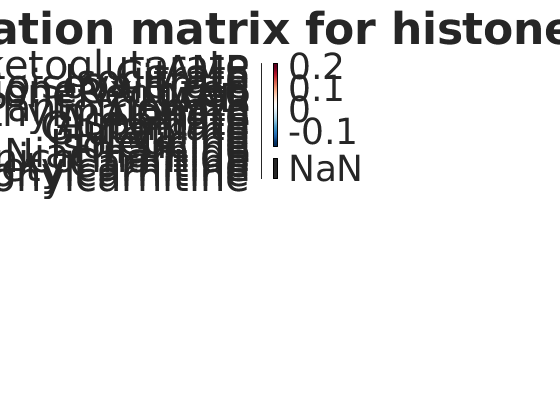


mask = pearsonmat;
mask(pearsonpval > 0.05) = NaN;

% Plot correlation matrix without p-value mask                            
heatmap(mask', 'colormap', redbluecmap, ...
        'YData', metabolites, ...
        'XData', markers, ...
        'Title', 'Filtered correlation matrix for histone methylation', ...
        'Fontsize', 30)
xlabel('Histone acetylation markers');
ylabel('Metabolites related to histone acetylation')

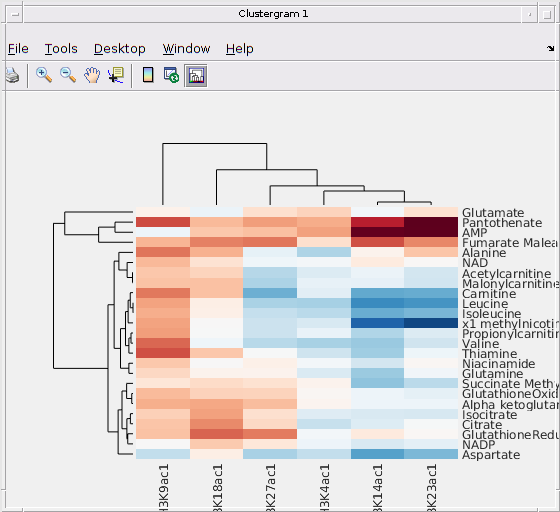

Clustergram object with 25 rows of nodes and 6 columns of nodes.




% Plot clustergram without p-value mask
clustergram(pearsonmat', ...
            'RowLabels', metabolites', ...
            'ColumnLabels', markers, ...
            'RowPdist', 'correlation', ...
            'ColumnPdist', 'correlation', ...
            'Colormap', redbluecmap)

#### Spearman rank correlation

I also wanted to look at rank correlations. Interestingly, the magnitude of the rank coefficients didnt change much. So I ommited this Spearman analysis for the remaining analyses.

% Compute pearson correlation coefficient matrix
[spearmanmat, spearmanpval] = corr(X, Y, ...
                                 'Type', 'Spearman');

% Plot correlation matrix without p-value mask                            
redbluecmap = imresize(redbluecmap, [1000, 3]); redbluecmap = min(max(redbluecmap, 0), 1);
metabolites = strrep(metabolites, '_', ' ');
heatmap(spearmanmat', 'colormap', redbluecmap, ...
        'YData', metabolites, ...
        'XData', markers)
% Plot clustergram without p-value mask
clustergram(spearmanmat', ...
            'RowLabels', metabolites', ...
            'ColumnLabels', markers, ...
            'RowPdist', 'correlation', ...
            'ColumnPdist', 'correlation', ...
            'Colormap', redbluecmap)

### Applying a mask

Next, I decided to look at these matrices using the p-value mask. Because there are NaNs, we can't make a clustergram for this set. 

mask = pearsonmat;
mask(pearsonpval > 0.05) = NaN;

% Plot correlation matrix without p-value mask                            
heatmap(mask', 'colormap', redbluecmap, ...
        'YData', metabolites, ...
        'XData', markers)